#  Initialization

clear all;

% accel data
% accelerometer = load("X02299_ConflictTaskRun1.mat"); % dirty
accelerometer = load("acc_run1.mat");
% a2 = load("acc_run2.mat");
sampling = accelerometer.samples_per_second;
data_length = length(accelerometer.channels{1}.data);
t = linspace(0, data_length/2, data_length);

% cued data
% cued_data = load('02299_1_2022_Oct_06_1223_V_cued_r_time.mat'); % dirty
cued_data = load('1330_1_2021_Jul_13_1449_V_cued_r_time.mat');
cued_data.stimonset = round(cued_data.stimonset * 1000);
cued_data.presstime = round(cued_data.presstime * 1000);

% first maximum of derivative to check t find movement
% find movement from vibration segmenting into timewindows from vibration
% csv with output
% check
% reference ideas
% abstract, discussion *suggestions, pay attention to data acquisition

% figure out onset vibrations -> segment
% ignore first trial -> from second onwards
% select vibration for each finger. SNR
% x = ms. 1s before next vibration. should have 200 segments
% onset conditions -> segmentation
% fz vibration >> movement
% list of onsets -> finger -> trial -> summary statistics

% Hi Chang, in the attached (subject x03004) both accelerometers should be 
% working. As you can see from the 'Presstime' the subject had a hard time hitting 
% the responsebox. '99' means no response (missed target). Use the first run to 
% establish what we talked about segmention from vibration-->triallist from 
% vibration+respons--> extraction of RTs, and then compare it to 'triallist' and 
% 'presstime'. Your output should be a CSV file with at least the following rows: 
% inputfinger, outputfinger, trialtype, vibration onset/offset, movement onset, 
% reaction time. 

accelerometer.channels{1} % different structure, how come?

ans = struct with fields:
                  data: [-0.3828 -0.3563 -0.3793 -0.3775 -0.3811 -0.2711 -0.3988 -0.3031 -0.3899 -0.2747 -0.4343 -0.3669 -0.4307 -0.3403 -0.3438 -0.3563 -0.3332 -0.3102 -0.2853 -0.4431 -0.3545 -0.4165 -0.3031 -0.4148 -0.3208 -0.3882 -0.2853 -0.2889 … ]
    samples_per_second: 2000
                  name: 'FDI-X - TSD109J / TSD109J1 - 200g Accel'
     frequency_divider: 1
                 units: 'g'


accelerometer.event_markers{3} % are these already segmented good?

ans = struct with fields:
             label: 'Segment 3'
      sample_index: 8002
         type_code: 'apnd'
              type: 'Append'
      date_created: '2021-07-13T12:50:11.632000+00:00'
    channel_number: -1
           channel: 'Global'


accelerometer.event_markers{2}

ans = struct with fields:
             label: 'Segment 2'
      sample_index: 4001
         type_code: 'apnd'
              type: 'Append'
      date_created: '2021-07-13T12:50:08.233000+00:00'
    channel_number: -1
           channel: 'Global'


accelerometer.event_markers{1}

ans = struct with fields:
             label: 'Segment 1'
      sample_index: 0
         type_code: 'apnd'
              type: 'Append'
      date_created: '2021-07-13T12:50:04.434000+00:00'
    channel_number: -1
           channel: 'Global'


# Raw plot

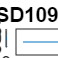

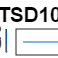

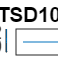

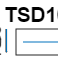

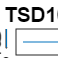

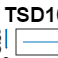

for i = 1:length(accelerometer.channels)
    figure()
    hold on
    plot(t, accelerometer.channels{i}.data)
    hold off
    
    title(accelerometer.channels{i}.name)
    ylabel(accelerometer.channels{i}.units)
    xlabel('seconds [s]')
    xlim([0,1e4])
    grid("on")
    legend("Accelerometer", 'Location','eastoutside')
end    

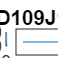

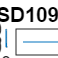

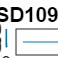

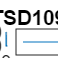

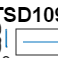

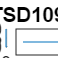

% FFT
fft_raw = zeros(data_length, length(accelerometer.channels));
for i = 1:length(accelerometer.channels)
    fft_raw(:, i) = abs(fft(accelerometer.channels{i}.data)).^2 ./ data_length;
end

f = (1:length(fft_raw)) * sampling / length(fft_raw);

for i = 1:length(accelerometer.channels)
    figure()

    hold on 
    plot(f, fft_raw(:,i))
    hold off

    title(accelerometer.channels{i}.name + "PS")
    ylabel('Magnitude')
    xlabel('fz [Hz]')
    grid("on")
    xlim([0, 400])
    ylim([0, 10])
    legend("Raw", 'Location','eastoutside')
end

# Filtering (isolating the vibration)

% Isolating vibration at 75 nd 175 Hz
cutoff_low = 120; 
cutoff_high = 130; 
filter_order = 5;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

vibration = zeros(data_length, length(accelerometer.channels));
for i = 1:length(accelerometer.channels)
    vibration(:,i) = abs(filtfilt(b, a , accelerometer.channels{i}.data));
end

filter_order = 3;
cutoff_low = 5;
[b,a] = butter(filter_order, cutoff_low/(sampling/2), 'low');

% temp = hilbert(vibration, data_length);
% vibration_envelope = abs(temp);
% clear('temp')
vibration_envelope = filtfilt(b,a, vibration) * 2;
% vibration_envelope(:,1) = vibration_envelope(:,1) * 20;
% vibration_envelope(:,4) = vibration_envelope(:,4) * 20;

[v_peaks_fdi, v_peaks_locs_fdi] = findpeaks(vibration_envelope(:,3), 'MinPeakProminence', 0.05);
[v_peaks_adm, v_peaks_locs_adm] = findpeaks(vibration_envelope(:,4), 'MinPeakProminence', 0.05);

% v_borders_fdi = getBorders(vibration_envelope(:,3), v_peaks_locs_fdi, v_peaks_fdi);
% v_borders_adm = getBorders(vibration_envelope(:,4), v_peaks_locs_adm, v_peaks_adm);

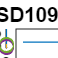

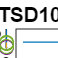

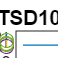

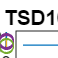

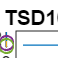

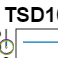

for i = 1:length(accelerometer.channels)
    figure()
    hold on
    plot(t, accelerometer.channels{i}.data - median(accelerometer.channels{i}.data))
    plot(t, vibration(:,i))
    plot(t, vibration_envelope(:,i))
    scatter(t(v_peaks_locs_adm), vibration_envelope(v_peaks_locs_adm, i))
    scatter(t(v_peaks_locs_fdi), vibration_envelope(v_peaks_locs_fdi, i))
    % scatter(t(v_borders_fdi(:,1)), movement_envelope(v_borders_fdi(:,1),i), marker = "x", LineWidth=2)
    % scatter(t(v_borders_fdi(:,2)), movement_envelope(v_borders_fdi(:,2),i), marker = "x", LineWidth=2)
    % scatter(t(v_borders_adm(:,1)), movement_envelope(v_borders_adm(:,1),i), marker = "x", LineWidth=2)
    % scatter(t(v_borders_adm(:,2)), movement_envelope(v_borders_adm(:,2),i), marker = "x", LineWidth=2)
    hold off
    
    title(accelerometer.channels{i}.name)
    ylabel(accelerometer.channels{i}.units)
    xlabel('mseconds [ms]')
    xlim([0,1e4])
    ylim([-0.01, 0.35])
    grid("on")
    legend("Accelerometer", 'Vibration', 'Envelope', 'Location','eastoutside')
end    

# Isolating the movement

cutoff_low = 1; 
cutoff_high = 10; % around maximum of non trained human movement
filter_order = 1;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

movement = zeros(data_length, length(accelerometer.channels));
for i = 1:length(accelerometer.channels)
    movement(:,i) = filtfilt(b, a , accelerometer.channels{i}.data);
end

filter_order = 3;
cutoff_low = 5;
[b,a] = butter(filter_order, cutoff_low/(sampling/2), 'low');

movement_envelope = abs(filtfilt(b,a, abs(movement)));

[m_peaks_fdi, m_peaks_locs_fdi] = findpeaks(movement_envelope(:,1), 'MinPeakProminence', 0.05);
[m_peaks_adm, m_peaks_locs_adm] = findpeaks(movement_envelope(:,4), 'MinPeakProminence', 0.05);

m_borders_fdi = getBorders(movement_envelope(:,1), m_peaks_locs_fdi, m_peaks_fdi);
m_borders_adm = getBorders(movement_envelope(:,4), m_peaks_locs_adm, m_peaks_adm);

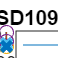

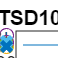

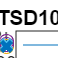

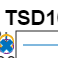

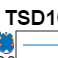

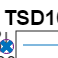

for i = 1:length(accelerometer.channels)
    figure()
    hold on
    % plot(t, accelerometer.channels{i}.data - median(accelerometer.channels{i}.data))
    % plot(t, vibration(:,i))
    % plot(t, vibration_envelope(:,i))
    plot(t, movement(:,i))
    plot(t, movement_envelope(:,i))
    scatter(t(m_peaks_locs_adm), movement_envelope(m_peaks_locs_adm, i))
    scatter(t(m_peaks_locs_fdi), movement_envelope(m_peaks_locs_fdi, i))
    scatter(t(m_borders_fdi(:,1)), movement_envelope(m_borders_fdi(:,1),i), marker = "x", LineWidth=2)
    scatter(t(m_borders_fdi(:,2)), movement_envelope(m_borders_fdi(:,2),i), marker = "x", LineWidth=2)
    scatter(t(m_borders_adm(:,1)), movement_envelope(m_borders_adm(:,1),i), marker = "x", LineWidth=2)
    scatter(t(m_borders_adm(:,2)), movement_envelope(m_borders_adm(:,2),i), marker = "x", LineWidth=2)
    hold off
    
    title(accelerometer.channels{i}.name)
    ylabel(accelerometer.channels{i}.units)
    xlabel('mseconds [ms]')
    xlim([5e3,1e4])
    ylim([-0.01, 0.3])
    grid("on")
    legend('Movement', 'Envelope M', 'Location','eastoutside')
end    

# Remove movement detection from vibration

% th = 4000; % based on accelerometer segments (2s)

indexes = getVibrationsInMovement(v_peaks_locs_fdi, m_borders_fdi);
v_peaks_fdi(indexes) = [];
v_peaks_locs_fdi(indexes) = [];

indexes = getVibrationsInMovement(v_peaks_locs_adm, m_borders_adm);
v_peaks_adm(indexes) = [];
v_peaks_locs_adm(indexes) = [];

threshold = [mean(v_peaks_fdi), mean(v_peaks_adm)];

% indexes = find(v_peaks_fdi < 0.15 * threshold(1))
% v_peaks_fdi(indexes) = [];
% v_peaks_locs_fdi(indexes) = [];

% indexes = find(v_peaks_adm < 0.15 * threshold(2))
% v_peaks_adm(indexes) = [];
% v_peaks_locs_adm(indexes) = [];

v_borders_fdi = getBorders(vibration_envelope(:,3), v_peaks_locs_fdi, v_peaks_fdi);
v_borders_adm = getBorders(vibration_envelope(:,4), v_peaks_locs_adm, v_peaks_adm);

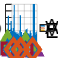

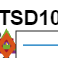

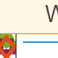

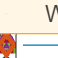

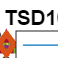

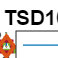

for i = 1:length(accelerometer.channels)
    figure()
    hold on
    plot(t, accelerometer.channels{i}.data - median(accelerometer.channels{i}.data))
    plot(t, vibration(:,i))
    plot(t, vibration_envelope(:,i))
    scatter(t(v_peaks_locs_adm), vibration_envelope(v_peaks_locs_adm, i), marker = "^", LineWidth=2)
    scatter(t(v_peaks_locs_fdi), vibration_envelope(v_peaks_locs_fdi, i), marker = "^", LineWidth=2)
    scatter(t(v_borders_fdi(:,1)), vibration_envelope(v_borders_fdi(:,1),i), marker = "square", LineWidth=2)
    scatter(t(v_borders_fdi(:,2)), vibration_envelope(v_borders_fdi(:,2),i), marker = "square", LineWidth=2)
    scatter(t(v_borders_adm(:,1)), vibration_envelope(v_borders_adm(:,1),i), marker = "diamond", LineWidth=2)
    scatter(t(v_borders_adm(:,2)), vibration_envelope(v_borders_adm(:,2),i), marker = "diamond", LineWidth=2)
    % xline(232723/2)
    % xline(234214/2)
    % yline(mean(v_peaks_fdi))
    % yline(mean(v_peaks_adm))
    hold off
    
    title(accelerometer.channels{i}.name)
    ylabel(accelerometer.channels{i}.units)
    xlabel('mseconds [ms]')
    xlim([0,1e4])
    % xlim([0,1e4])
    ylim([-0.01, 0.35])
    grid("on")
    legend("Accelerometer", 'Vibration', 'Envelope', 'Location','eastoutside')
end

% use threshold, lock in for 2000ms, get data
% search for movement and then detect vibration
% trial list w rt
% put something to manually look for stuff

# Segmenting by vibrations

vibration_onsets = sort([v_borders_fdi(:,1)', v_borders_adm(:,1)']);
% if there are two too close need to get the first one bc it's a vibration
vibration_onsets(diff(vibration_onsets) < 3000)

ans =        38964       76737       77778      236751      239260      396817      608881      756921      816934      819737      828944      876951      920961


vibration_onsets(diff(vibration_onsets) < 3000) = [];

% determining vibration finger 1 -> FDI, 2 -> ADM, 0 -> not detected
vibration_onset_finger = zeros(length(vibration_onsets),1);
for i = 1:length(vibration_onsets)
    if ismember(vibration_onsets(i), v_borders_fdi)
        vibration_onset_finger(i) = 1;
    end
    if ismember(vibration_onsets(i), v_borders_adm)
        vibration_onset_finger(i) = 2;
    end
end

# Determining vibration finger

% press_finger 1 -> FDI, 2 -> ADM, 0 -> not detected
movement_finger = zeros(length(vibration_onsets),1);
for i = 1:length(vibration_onsets)
    start = vibration_onsets(i);
    if i < length(vibration_onsets)
        finish = vibration_onsets(i+1);
    else
        finish = data_length;
    end

    if ~isempty(m_peaks_locs_fdi(m_peaks_locs_fdi > start & m_peaks_locs_fdi < finish))
        movement_finger(i) = 1;
    end
    if ~isempty(m_peaks_locs_adm(m_peaks_locs_adm > start & m_peaks_locs_adm < finish))
        movement_finger(i) = 2;
    end
    if ~isempty(m_peaks_locs_fdi(m_peaks_locs_fdi > start & m_peaks_locs_fdi < finish)) && ~isempty(m_peaks_locs_adm(m_peaks_locs_adm > start & m_peaks_locs_adm < finish))
        movement_finger(i) = 0;
    end
end

# Determining test type

test_type = zeros(length(vibration_onsets),1);
for i = 1:length(vibration_onsets)
    if vibration_onset_finger(i) == 0 || movement_finger(i) == 0
        continue;
    end
    if vibration_onset_finger(i) == 1 && movement_finger(i) == 1
        test_type(i) = 3;
    end
    if vibration_onset_finger(i) == 2 && movement_finger(i) == 1
        test_type(i) = 2;
    end
    if vibration_onset_finger(i) == 1 && movement_finger(i) == 2
        test_type(i) = 1;
    end
    if vibration_onset_finger(i) == 2 && movement_finger(i) == 2
        test_type(i) = 4;
    end
end
test_type

test_type =      1
     4
     4
     1
     2
     2
     3
     4
     3
     3



% TODO: csv and change findborders

t1_index = find(cued_data.triallist == 1);
t2_index = find(cued_data.triallist == 2);
t3_index = find(cued_data.triallist == 3);
t4_index = find(cued_data.triallist == 4);

disp("T1: " + (length(find(test_type(t1_index) == 1))) / (length(test_type(t1_index))) * 100 + "%")

Index exceeds the number of array elements. Index must not exceed 229.

disp("T2: " + (length(find(test_type(t2_index) == 2))) / (length(test_type(t2_index))) * 100 + "%")
disp("T3: " + (length(find(test_type(t3_index) == 3))) / (length(test_type(t3_index))) * 100 + "%")
disp("T4: " + (length(find(test_type(t4_index) == 4))) / (length(test_type(t4_index))) * 100 + "%")